# Controle de posição

clear all;
clc;
close all;

## Análise de malha aberta

Np = 2979

Np = 2979

Dp = [1 28 0]

Dp =      1    28     0


Gp = tf(Np,Dp)                              % malha de posição

Gp =
 
     2979
  ----------
  s^2 + 28 s
 
Continuous-time transfer function.



polos = roots(cell2mat(Gp.Denominator))     % estabilidade

polos =      0
   -28


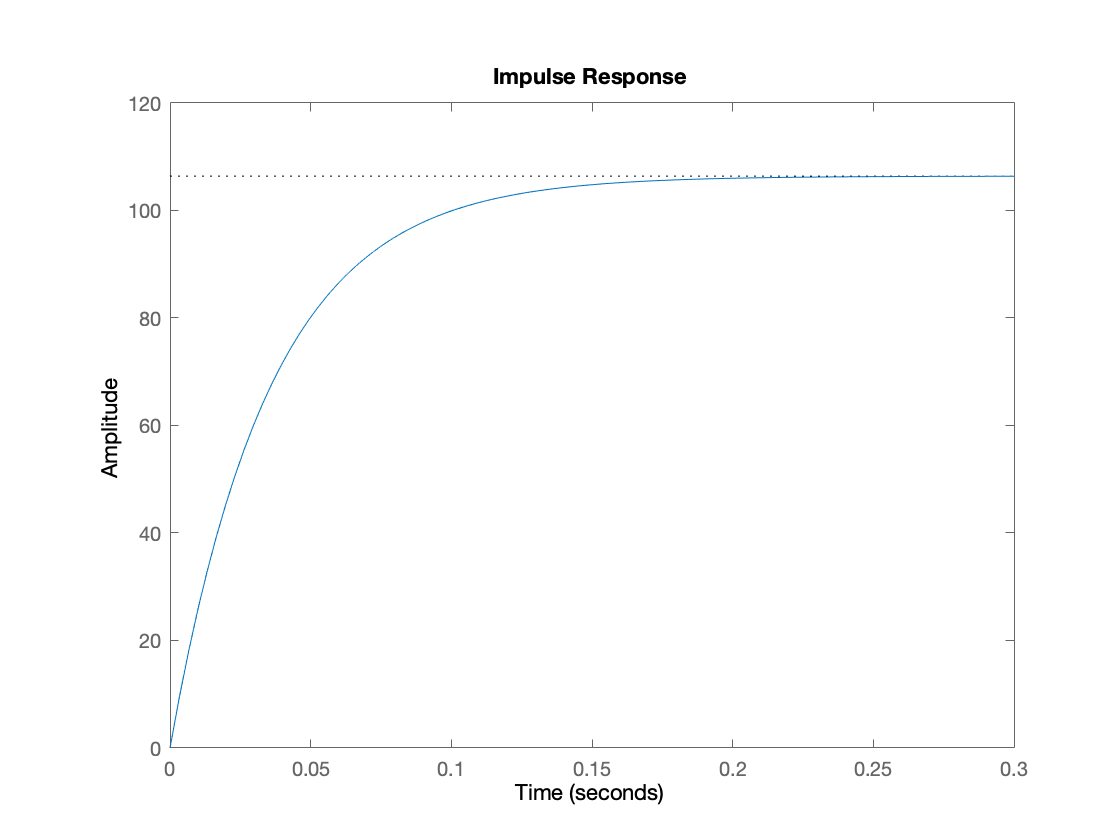

% Erro estacionário ao degrau é nulo em malha fechada

impulse(Gp)

## Análise de controle proporcional

% Analise em malha fechada

Kp  = 1;
Gc  = Kp;
Gma = Gc*Gp;
Gmf = feedback(Gma,1)           % ganho em malha fechada

Gmf =
 
        2979
  -----------------
  s^2 + 28 s + 2979
 
Continuous-time transfer function.




polosMF = roots(cell2mat(Gmf.Denominator))

polosMF =  -14.0000 +52.7541i
 -14.0000 -52.7541i


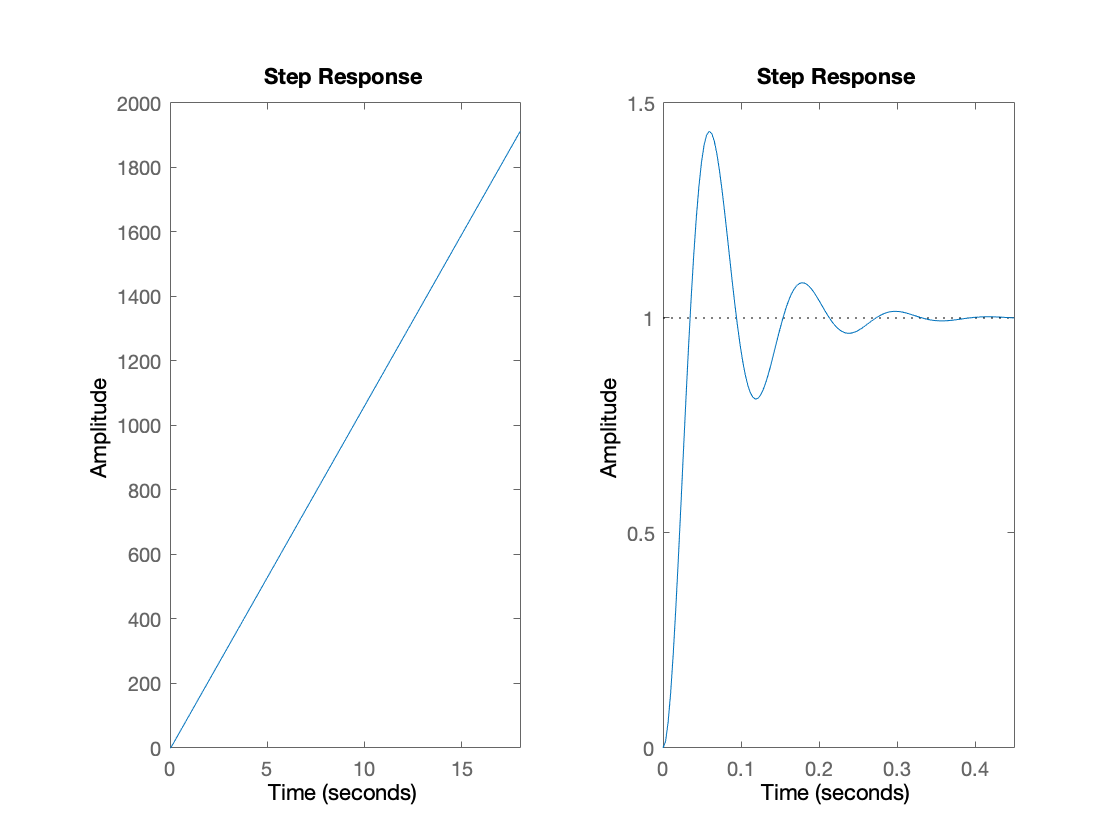

figure()

% Malha aberta
subplot(1,2,1)
step(Gp)

% Malha fechada
subplot(1,2,2)
step(Gmf)

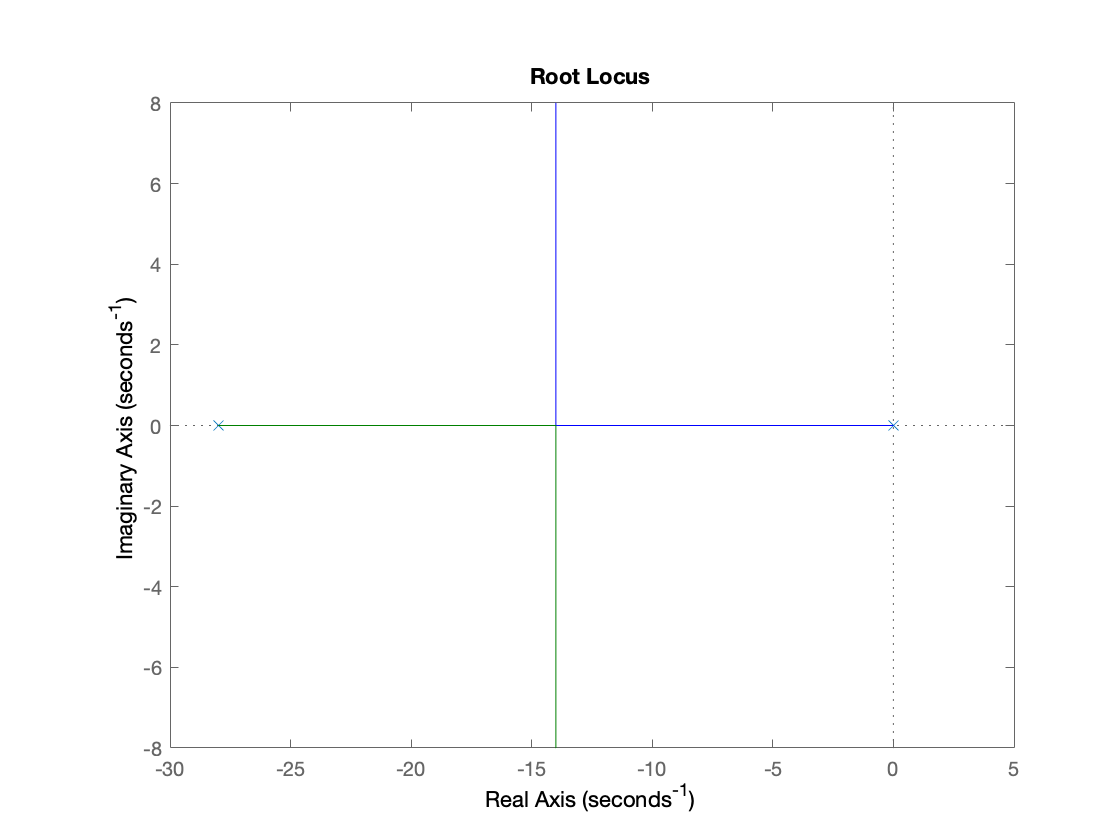

% Análise dos polos de malha fechada variando com o ganho Kp

figure()
rlocus(Gma)

## Projetando  o controlador


% Kp Gma = -1 
% polo de malha fechada fosse -14

% Gma(-14)
 
Gma

Gma =
 
     2979
  ----------
  s^2 + 28 s
 
Continuous-time transfer function.




Gmap = evalfr(Gma,-14)

Gmap = -15.1990

Kp = -1/Gmap

Kp = 0.0658

GmfN = feedback(Kp*Gma,1)

GmfN =
 
        196
  ----------------
  s^2 + 28 s + 196
 
Continuous-time transfer function.



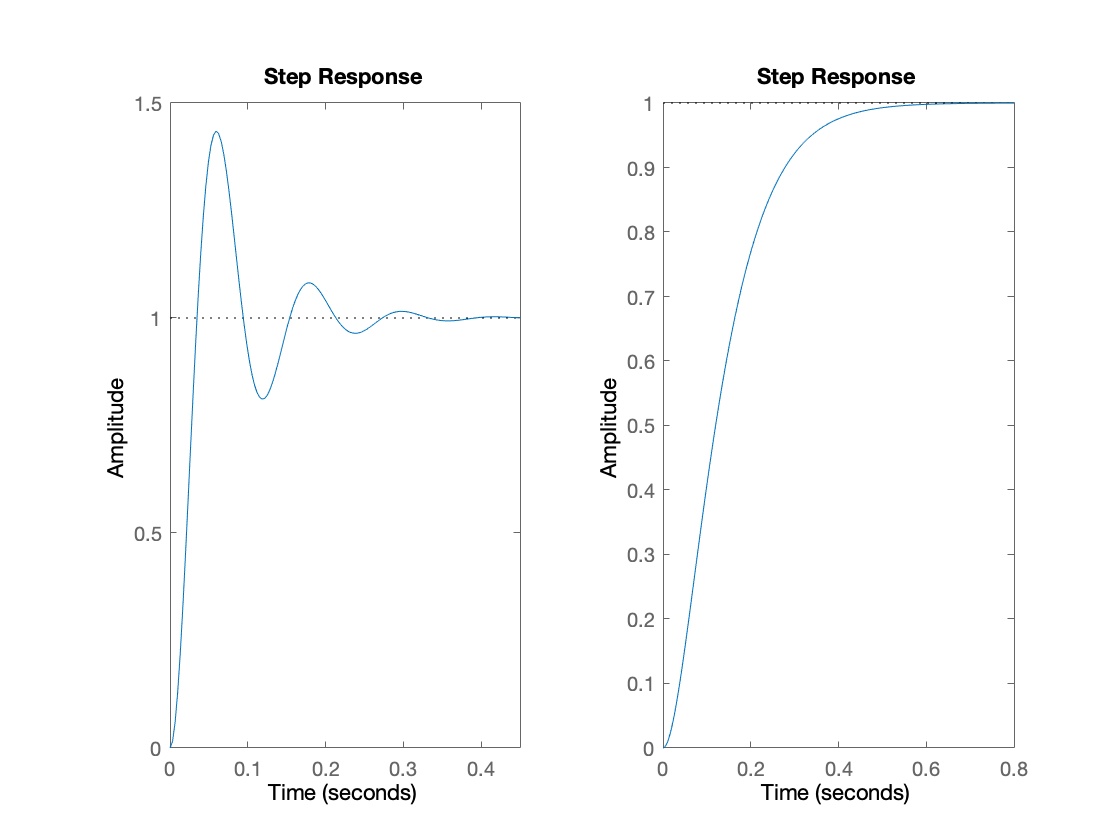


figure()

% Malha aberta
subplot(1,2,1)
step(Gmf)

% Malha fechada
subplot(1,2,2)
step(GmfN)

% O controlador que reduz a oscilação é Kp = 0.0658

## Análise temporal

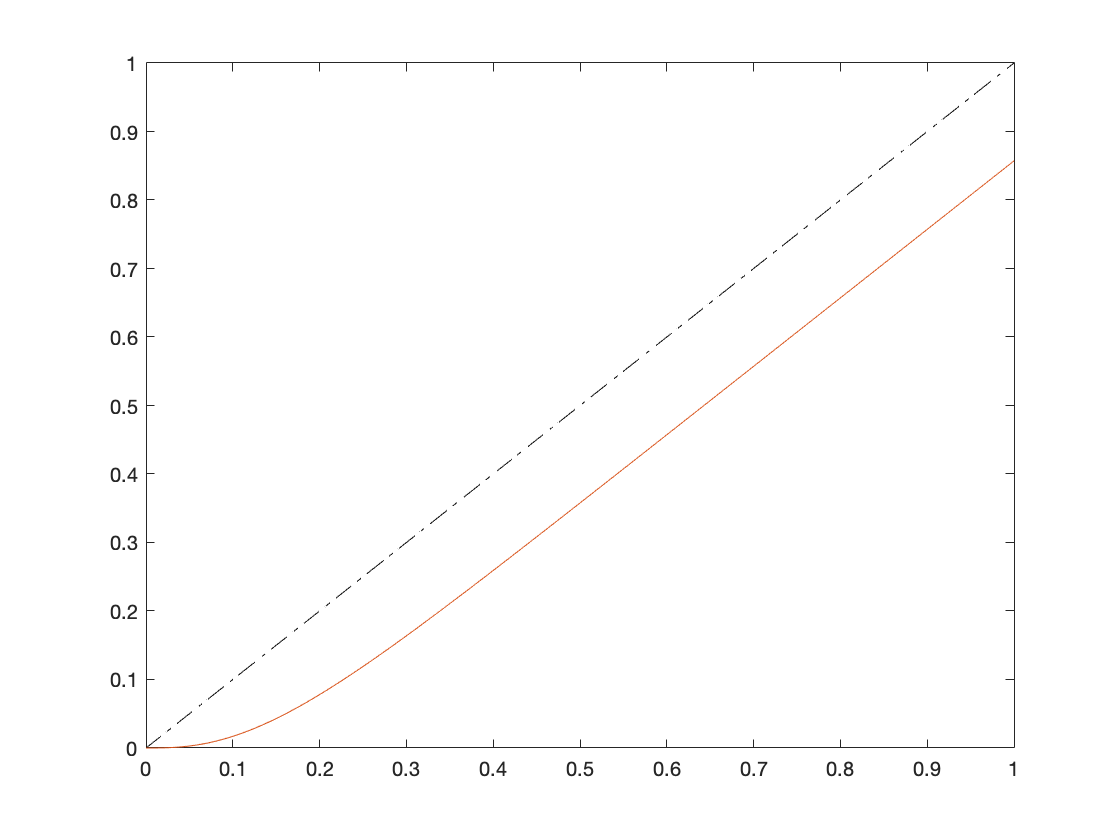

% Análise de rroa estacionário a rampa unitária

tempo = linspace(0,1,1000);
rampa =  tempo;

[PosicaoRampa,tempo] = lsim(GmfN,rampa,tempo);

figure()

plot(tempo,rampa,'k-.',tempo, PosicaoRampa)

% Erro estacionário - este erro é aceitável ?

erro = rampa(end) - PosicaoRampa(end)

erro = 0.1429

## Análise em frequência

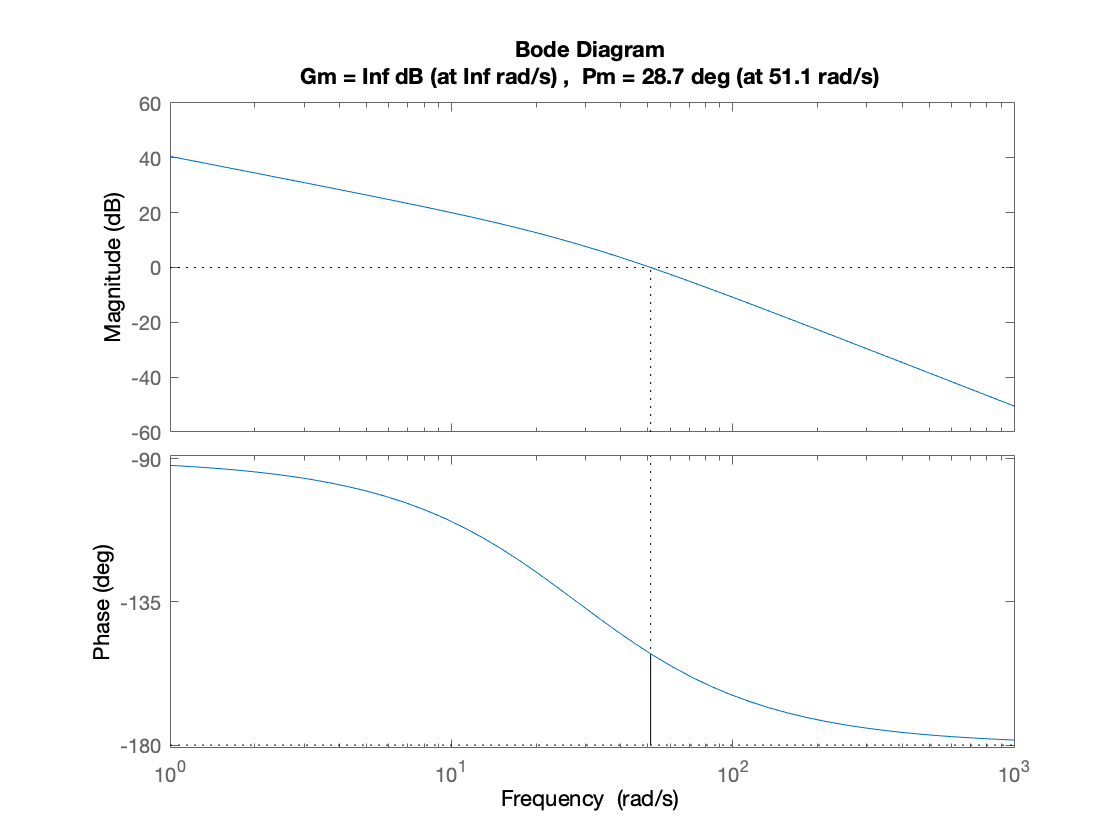

% A margenm de fase é adequada?

margin(Gma)

## Projeto do controlador

- Erro estacionário ao degrau nulo - OK

- Erro estacionário a rampa menor que 0.1 (10%) - NOK

- Margem de Fase  MF = 50 deg - NOK

% escolha do tipo de controlador
% PI ou Avanço ou Atraso --> Avanço - reduzir o erro estacionário e
% aumentar a marge de fase

% Gc(s) = k(Ts +1)/(aTs+1)   --> 0 < a < 1

% determinar K e T - a


## Validação